# OQPSK

% Definer systemkomponenter
oqpskmod = comm.OQPSKModulator('BitInput', true);
oqpskdemod = comm.OQPSKDemodulator('BitOutput', true);
channel = comm.AWGNChannel('EbNo', 20, 'BitsPerSymbol', 2);

% Definer raised cosine-filtere
span = 10;                 % Filter span (antall symboler)
samplesPerSymbol = 4;      % Antall prøver per symbol
rolloff = 0;               % Rolloff-faktor

txFilter = comm.RaisedCosineTransmitFilter( ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'OutputSamplesPerSymbol', samplesPerSymbol);

rxFilter = comm.RaisedCosineReceiveFilter( ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', span, ...
    'InputSamplesPerSymbol', samplesPerSymbol, ...
    'DecimationFactor', samplesPerSymbol);

% Timing synchronizer
symbolSync = comm.SymbolSynchronizer( ...
    'SamplesPerSymbol', samplesPerSymbol, ...
    'DampingFactor', 1, ...
    'NormalizedLoopBandwidth', 0.01, ...
    'TimingErrorDetector', 'Gardner (non-data-aided)');

% Generer en tilfeldig binær sekvens
numBits = 1e4;
data = randi([0 1], numBits, 1);

% Moduler signalet
txSignal = oqpskmod(data);

% Filtrer ved senderen
txFilteredSignal = txFilter(txSignal);


% Pass the delayed signal through the AWGN channel
rxSignal = channel(txFilteredSignal);

% Filtrer ved mottakeren
rxFilteredSignal = rxFilter(rxSignal);

% Timing synchronization
synchronizedSignal = symbolSync(rxFilteredSignal);

% Carrier synchronizer
carrierSync = comm.CarrierSynchronizer( ...
    'Modulation', 'OQPSK', ...
    'SamplesPerSymbol', samplesPerSymbol, ...
    'DampingFactor', 1, ...
    'NormalizedLoopBandwidth', 0.01);

% Apply carrier synchronization
phaseCorrectedSignal = carrierSync(synchronizedSignal);

% Demoduler signalet
receivedData = oqpskdemod(rxFilteredSignal);

% Beregn feiltakt (BER)
errorRate = comm.ErrorRate;
ber = errorRate(data, receivedData);
disp(['Bit Error Rate: ', num2str(ber(1))]);

Bit Error Rate: 0.4972


# Visualisering

## Tidsserie

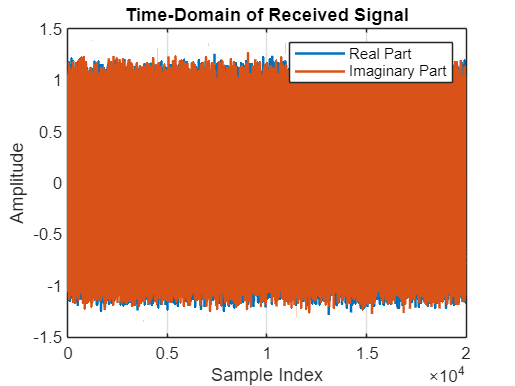

figure;
plot(real(rxFilteredSignal), 'LineWidth', 1.5,'DisplayName','Real Part');
hold on;
plot(imag(rxFilteredSignal), 'LineWidth', 1.5,'DisplayName','Imaginary Part');
title('Time-Domain of Received Signal');
xlabel('Sample Index');
ylabel('Amplitude');
legend();
grid on;
hold off;

## Power Spectrum Density

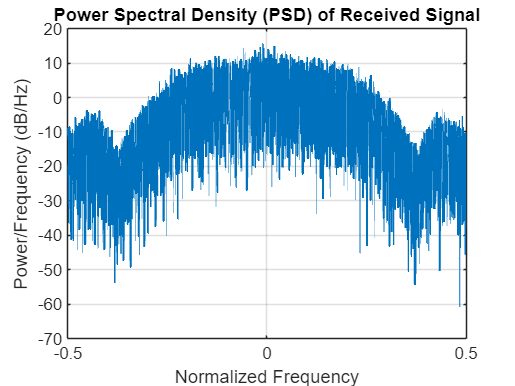

figure;
[psdValues, psdFreq] = periodogram(rxFilteredSignal, [], [], 1, 'centered'); % Bruk periodogram for PSD
plot(psdFreq, 10*log10(psdValues), 'LineWidth', 1.5);
title('Power Spectral Density (PSD) of Received Signal');
xlabel('Normalized Frequency');
ylabel('Power/Frequency (dB/Hz)');
grid on;

## Konstelasjon

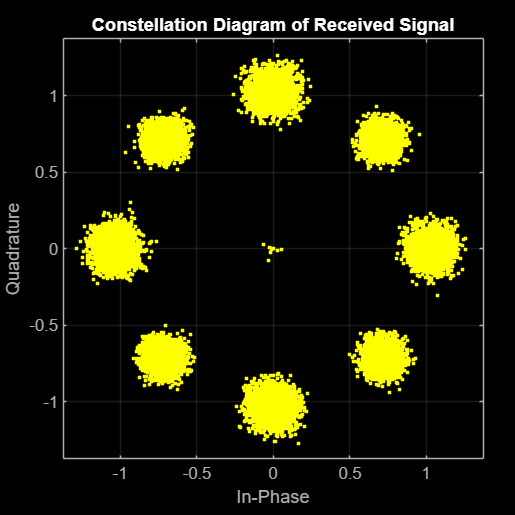

figure;
scatterplot(rxFilteredSignal);
title('Constellation Diagram of Received Signal');
grid on;

## Eye-Diagram

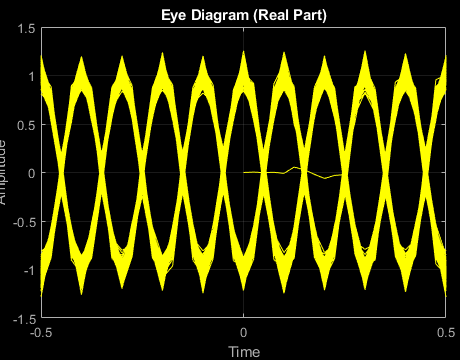

% Bruk eyediagram-funksjonen
figure;
eyediagram(real(rxFilteredSignal), samplesPerSymbol * span);
title('Eye Diagram (Real Part)');
xlabel('Time');
ylabel('Amplitude');
grid on;

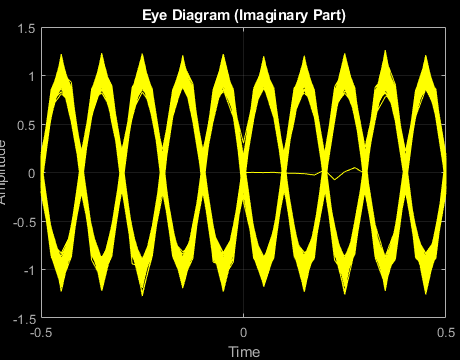


% Hvis du vil analysere den imaginære delen:
figure;
eyediagram(imag(rxFilteredSignal), samplesPerSymbol * span);
title('Eye Diagram (Imaginary Part)');
xlabel('Time');
ylabel('Amplitude');
grid on;